# Classification Assignment Live Script (Part 1 - Simple Dataset Clustering)

#### Initialization

clear; clc; close all

## Load, Partition and Normalize Data

data = load("haberman.data");
[trnData, chkData, tstData] = partition_normalize(data);

## TSK-1 - Class Independent Subtractive Clusterring

#### Generate Model

tsk1_genfisOptionsStruct = genfisOptions('SubtractiveClustering', ...
    'ClusterInfluenceRange', 0.3);
tsk1_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk1_genfisOptionsStruct);

% Manually change output to constant - improves accuracy approx 5%
for i=1:length(tsk1_initFIS.output.mf)
    tsk1_initFIS.output.mf(i).type = 'constant';
    tsk1_initFIS.output.mf(i).params = 1.5;
end

tsk1_anfisOptionsStruct = anfisOptions('InitialFIS', tsk1_initFIS, ...
                'EpochNumber', 600, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### Train Model

[tsk1_finalFIS, tsk1_trainError, ~, tsk1_valFIS, tsk1_valError] = ...
    anfis(trnData, tsk1_anfisOptionsStruct);

ANFIS info:
	Number of nodes: 70
	Number of linear parameters: 8
	Number of nonlinear parameters: 48
	Total number of parameters: 56
	Number of training data pairs: 190
	Number of checking data pairs: 61
	Number of fuzzy rules: 8


Start training ANFIS ...

1 	 0.417883 	 0.452918
2 	 0.413156 	 0.446406
3 	 0.405375 	 0.446341
4 	 0.402666 	 0.442289
Step size increases to 0.011000 after epoch 5.
5 	 0.399975 	 0.437934
6 	 0.397647 	 0.436377
7 	 0.395533 	 0.433337
8 	 0.39466 	 0.442038
Step size increases to 0.012100 after epoch 9.
9 	 0.394234 	 0.432887
10 	 0.392639 	 0.439405
11 	 0.390086 	 0.434637
12 	 0.387726 	 0.435901
Step size increases to 0.013310 after epoch 13.
13 	 0.385866 	 0.433776
14 	 0.384471 	 0.440503
15 	 0.384014 	 0.434097
16 	 0.382678 	 0.442011
Step size increases to 0.014641 after epoch 17.
17 	 0.381469 	 0.434386
18 	 0.380813 	 0.441722
19 	 0.380486 	 0.433771
20 	 0.378653 	 0.438305
Step size increases to 0.016105 after epoch 21.
21 	 0.378064 


% Make Predictions & Round Data
tsk1_Y = evalfis(tsk1_valFIS, tstData(:,1:end-1));
tsk1_Y = round(tsk1_Y);
tsk1_Y(tsk1_Y < 1) = 1;
tsk1_Y(tsk1_Y > 2) = 2;

% Calculate performance metrics
[tsk1_errorMat, tsk1_accuracy, tsk1_producerAcc, tsk1_userAcc, tsk1_k] = metrics(tstData, tsk1_Y);

## TSK-2 - Class Independent Subtractive Clusterring

#### Generate Model

tsk2_genfisOptionsStruct = genfisOptions('SubtractiveClustering', ...
    'ClusterInfluenceRange', 0.8);
tsk2_initFIS = genfis(trnData(:, 1:(end-1)), trnData(:, end), tsk2_genfisOptionsStruct);

% Manually change output to constant
for i=1:length(tsk2_initFIS.output.mf)
    tsk2_initFIS.output.mf(i).type = 'constant';
    tsk2_initFIS.output.mf(i).params = 1.5;
end

tsk2_anfisOptionsStruct = anfisOptions('InitialFIS', tsk2_initFIS, ...
                'EpochNumber', 600, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

#### Train Model

[tsk2_finalFIS, tsk2_trainError, ~, tsk2_valFIS, tsk2_valError] = ...
    anfis(trnData, tsk2_anfisOptionsStruct);

ANFIS info:
	Number of nodes: 22
	Number of linear parameters: 2
	Number of nonlinear parameters: 12
	Total number of parameters: 14
	Number of training data pairs: 190
	Number of checking data pairs: 61
	Number of fuzzy rules: 2


Start training ANFIS ...

1 	 0.439034 	 0.438228
2 	 0.437562 	 0.437503
3 	 0.436056 	 0.436591
4 	 0.434557 	 0.435517
Step size increases to 0.011000 after epoch 5.
5 	 0.433033 	 0.434324
6 	 0.431441 	 0.433046
7 	 0.429573 	 0.431567
8 	 0.427569 	 0.430041
Step size increases to 0.012100 after epoch 9.
9 	 0.425442 	 0.428504
10 	 0.423231 	 0.427005
11 	 0.420779 	 0.425478
12 	 0.418409 	 0.424184
Step size increases to 0.013310 after epoch 13.
13 	 0.416236 	 0.423254
14 	 0.414357 	 0.422847
15 	 0.412704 	 0.423217
16 	 0.411482 	 0.424748
Step size increases to 0.014641 after epoch 17.
17 	 0.410606 	 0.427686
18 	 0.409979 	 0.431752
19 	 0.409519 	 0.436292
20 	 0.409234 	 0.438821
Step size increases to 0.016105 after epoch 21.
21 	 0.409031


% Make Predictions & Round Data
tsk2_Y = evalfis(tsk2_valFIS, tstData(:,1:end-1));
tsk2_Y = round(tsk2_Y);
tsk2_Y(tsk2_Y < 1) = 1;
tsk2_Y(tsk2_Y > 2) = 2;

% Calculate performance metrics
[tsk2_errorMat, tsk2_accuracy, tsk2_producerAcc, tsk2_userAcc, tsk2_k] = metrics(tstData, tsk2_Y);

## TSK-3 - Class Based Subtractive Clusterring

#### Build Model

% Build class clusters
tsk3_radius = 0.5;
[tsk3_c1, tsk3_sig1] = subclust(trnData(trnData(:, end) == 1,:), tsk3_radius);
[tsk3_c2, tsk3_sig2] = subclust(trnData(trnData(:, end) == 2,:), tsk3_radius);
rulesNum = size(tsk3_c1, 1) + size(tsk3_c2, 1);

% Construct FIS
tsk3_initFIS = sugfis();

% Configure Input - Output
names_in={'in1','in2','in3'};
for i = 1:size(names_in, 2)
    tsk3_initFIS = addInput(tsk3_initFIS, [min(data(:,i)) max(data(:,i))], Name=names_in{i});
end
tsk3_initFIS = addOutput(tsk3_initFIS, [1 2], Name='out1');

% Input Membership Functions
for i = 1:size(trnData, 2) - 1
    for j = 1:size(tsk3_c1,1)
        tsk3_initFIS = addMF(tsk3_initFIS, names_in{i}, 'gaussmf', [tsk3_sig1(i) tsk3_c1(j,i)], Name=sprintf("mf_%d", j));
    end
    for j = 1:size(tsk3_c2,1)
        tsk3_initFIS = addMF(tsk3_initFIS, names_in{i}, 'gaussmf', [tsk3_sig2(i) tsk3_c2(j,i)], Name=sprintf("mf_%d", size(tsk3_c1,1) + j));
    end
end

% Output Membership Functions
params = [ones(1, size(tsk3_c1,1)) ones(1, size(tsk3_c2,1)) * 2];
for i = 1:rulesNum
    tsk3_initFIS = addMF(tsk3_initFIS, 'out1', 'constant', params(i), Name=sprintf("mf_%d", i));
end

% FIS Rule Base
ruleList = zeros(rulesNum, size(trnData,2));
for i = 1:size(ruleList,1)
    ruleList(i,:) = i;
end
ruleList = [ruleList ones(rulesNum,2)];
tsk3_initFIS = addRule(tsk3_initFIS, ruleList);

#### Train Model

tsk3_anfisOptionsStruct = anfisOptions('InitialFIS', tsk3_initFIS, ...
                'EpochNumber', 600, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

[tsk3_finalFIS, tsk3_trainError, ~, tsk3_valFIS, tsk3_valError] = ...
    anfis(trnData, tsk3_anfisOptionsStruct);

ANFIS info:
	Number of nodes: 70
	Number of linear parameters: 8
	Number of nonlinear parameters: 48
	Total number of parameters: 56
	Number of training data pairs: 190
	Number of checking data pairs: 61
	Number of fuzzy rules: 8


Start training ANFIS ...

1 	 0.41084 	 0.475688
2 	 0.408167 	 0.486994
3 	 0.405337 	 0.500604
4 	 0.402709 	 0.509663
Step size increases to 0.011000 after epoch 5.
5 	 0.400457 	 0.510522
6 	 0.398494 	 0.505303
7 	 0.396525 	 0.496464
8 	 0.394694 	 0.486944
Step size increases to 0.012100 after epoch 9.
9 	 0.393008 	 0.477895
10 	 0.391496 	 0.469862
11 	 0.390049 	 0.462689
12 	 0.388806 	 0.458109
Step size increases to 0.013310 after epoch 13.
13 	 0.387703 	 0.457405
14 	 0.386656 	 0.462146
15 	 0.385478 	 0.474239
16 	 0.384229 	 0.490631
Step size increases to 0.014641 after epoch 17.
17 	 0.382978 	 0.501668
18 	 0.381811 	 0.502061
19 	 0.38063 	 0.498387
20 	 0.379482 	 0.495499
Step size increases to 0.016105 after epoch 21.
21 	 0.378364 	


% Make Predictions & Round Data
tsk3_Y = evalfis(tsk3_valFIS, tstData(:,1:end-1));
tsk3_Y = round(tsk3_Y);
tsk3_Y(tsk3_Y < 1) = 1;
tsk3_Y(tsk3_Y > 2) = 2;

% Calculate performance metrics
[tsk3_errorMat, tsk3_accuracy, tsk3_producerAcc, tsk3_userAcc, tsk3_k] = metrics(tstData, tsk3_Y);

## TSK-4 - Class Based Subtractive Clusterring

#### Build Model

% Build class clusters
tsk4_radius = 0.7;
[tsk4_c1, tsk4_sig1] = subclust(trnData(trnData(:, end) == 1,:), tsk4_radius);
[tsk4_c2, tsk4_sig2] = subclust(trnData(trnData(:, end) == 2,:), tsk4_radius);
rulesNum = size(tsk4_c1, 1) + size(tsk4_c2, 1);

% Construct FIS
tsk4_initFIS = sugfis();

% Configure Input - Output
names_in={'in1','in2','in3'};
for i = 1:size(names_in, 2)
    %tsk4_initFIS = addvar(tsk4_initFIS, 'input', names_in{i}, [min(data(:,i)) max(data(:,i))]);
    tsk4_initFIS = addInput(tsk4_initFIS, [min(data(:,i)) max(data(:,i))], Name=names_in{i});
end
%tsk4_initFIS = addvar(tsk4_initFIS, 'output', 'out1',[1 2]);
tsk4_initFIS = addOutput(tsk4_initFIS, [1 2], Name='out1');

% Input Membership Functions
for i = 1:size(trnData, 2) - 1
    for j = 1:size(tsk4_c1,1)
        % tsk4_initFIS = addmf(tsk4_initFIS, 'input', i, sprintf("mf_%d", j), 'gaussmf', [tsk4_sig1(i) tsk4_c1(j,i)]);
        tsk4_initFIS = addMF(tsk4_initFIS, names_in{i}, 'gaussmf', [tsk4_sig1(i) tsk4_c1(j,i)], Name=sprintf("mf_%d", j));
    end
    for j = 1:size(tsk4_c2,1)
        %tsk4_initFIS = addmf(tsk4_initFIS, 'input', i, sprintf("mf_%d", size(tsk4_c1,1) + j), 'gaussmf', [tsk4_sig2(i) tsk4_c2(j,i)]);
        tsk4_initFIS = addMF(tsk4_initFIS, names_in{i}, 'gaussmf', [tsk4_sig2(i) tsk4_c2(j,i)], Name=sprintf("mf_%d", size(tsk4_c1,1) + j));
    end
end

% Output Membership Functions
params = [ones(1, size(tsk4_c1,1)) ones(1, size(tsk4_c2,1)) * 2];
for i = 1:rulesNum
    %tsk4_initFIS = addmf(tsk4_initFIS, 'output', 1, sprintf("mf_%d", i), 'constant', params(i));
    tsk4_initFIS = addMF(tsk4_initFIS, 'out1', 'constant', params(i), Name=sprintf("mf_%d", i));
end

% FIS Rule Base
ruleList = zeros(rulesNum, size(trnData,2));
for i = 1:size(ruleList,1)
    ruleList(i,:) = i;
end
ruleList = [ruleList ones(rulesNum,2)];
tsk4_initFIS = addRule(tsk4_initFIS, ruleList);

#### Train Model

tsk4_anfisOptionsStruct = anfisOptions('InitialFIS', tsk4_initFIS, ...
                'EpochNumber', 600, ...
                'ValidationData', chkData, ...
                'OptimizationMethod', 1);

[tsk4_finalFIS, tsk4_trainError, ~, tsk4_valFIS, tsk4_valError] = ...
    anfis(trnData, tsk4_anfisOptionsStruct);

ANFIS info:
	Number of nodes: 46
	Number of linear parameters: 5
	Number of nonlinear parameters: 30
	Total number of parameters: 35
	Number of training data pairs: 190
	Number of checking data pairs: 61
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 0.422365 	 0.501036
2 	 0.420564 	 0.499878
3 	 0.418741 	 0.49697
4 	 0.416917 	 0.492612
Step size increases to 0.011000 after epoch 5.
5 	 0.415115 	 0.487139
6 	 0.41336 	 0.480901
7 	 0.411504 	 0.473543
8 	 0.40974 	 0.466053
Step size increases to 0.012100 after epoch 9.
9 	 0.408074 	 0.458727
10 	 0.406502 	 0.45176
11 	 0.404869 	 0.444612
12 	 0.40332 	 0.438054
Step size increases to 0.013310 after epoch 13.
13 	 0.401836 	 0.432044
14 	 0.400411 	 0.426515
15 	 0.398916 	 0.420922
16 	 0.397531 	 0.415847
Step size increases to 0.014641 after epoch 17.
17 	 0.396307 	 0.411337
18 	 0.39527 	 0.407477
19 	 0.394284 	 0.404109
20 	 0.393374 	 0.401721
Step size increases to 0.016105 after epoch 21.
21 	 0.39253 	 0.39


% Make Predictions & Round Data
tsk4_Y = evalfis(tsk4_valFIS, tstData(:,1:end-1));
tsk4_Y = round(tsk4_Y);
tsk4_Y(tsk4_Y < 1) = 1;
tsk4_Y(tsk4_Y > 2) = 2;

% Calculate performance metrics
[tsk4_errorMat, tsk4_accuracy, tsk4_producerAcc, tsk4_userAcc, tsk4_k] = metrics(tstData, tsk4_Y);

#### Error Matrices

errMat_colNames = {'ActualC1','ActualC2'};
errMat_rowNames = {'Predicted-C1','Predicted-C2'};
tsk1_errorMat = array2table(tsk1_errorMat, 'VariableNames', errMat_colNames, 'RowNames', errMat_rowNames);
tsk2_errorMat = array2table(tsk2_errorMat, 'VariableNames', errMat_colNames, 'RowNames', errMat_rowNames);
tsk3_errorMat = array2table(tsk3_errorMat, 'VariableNames', errMat_colNames, 'RowNames', errMat_rowNames);
tsk4_errorMat = array2table(tsk4_errorMat, 'VariableNames', errMat_colNames, 'RowNames', errMat_rowNames);

#### Stats, Learning Curves, Final MFs

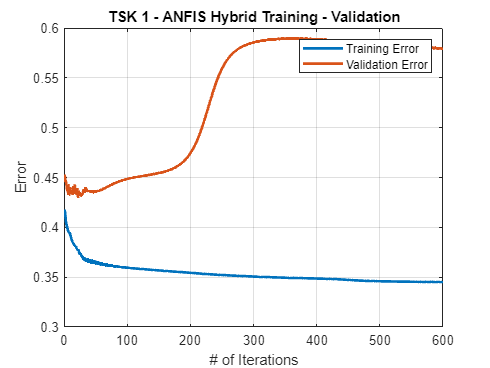

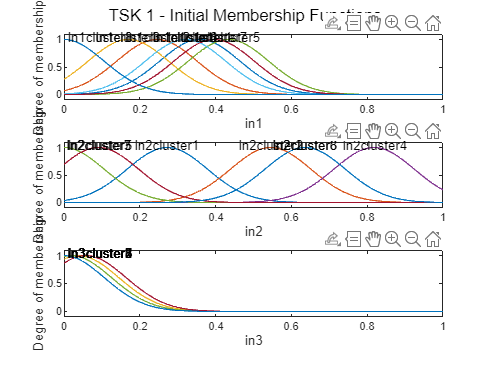

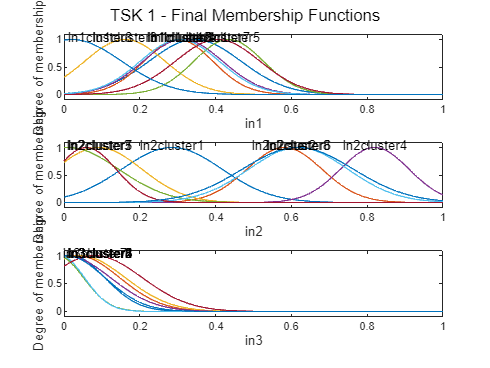

stats_graphs(1, tsk1_valFIS, tsk1_initFIS, chkData, tsk1_trainError, tsk1_valError);

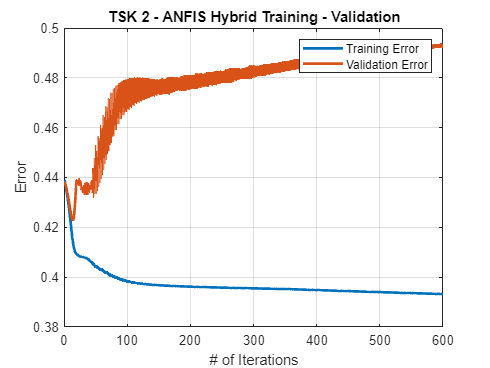

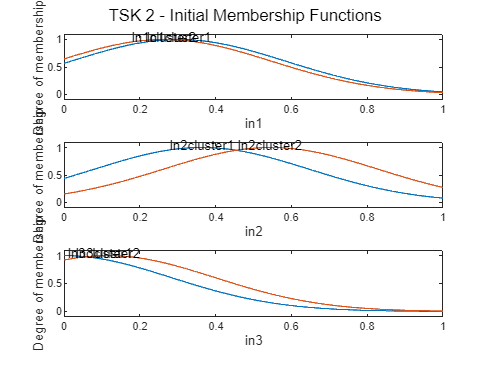

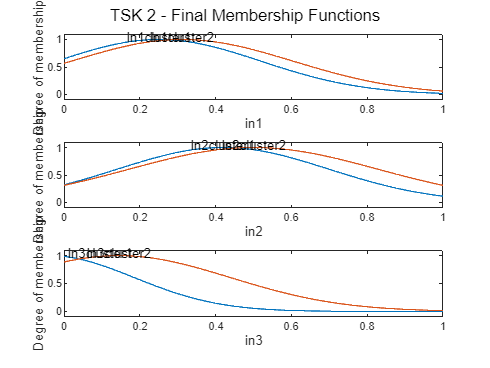

stats_graphs(2, tsk2_valFIS, tsk2_initFIS, chkData, tsk2_trainError, tsk2_valError);

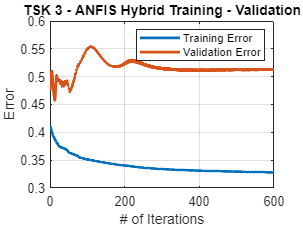

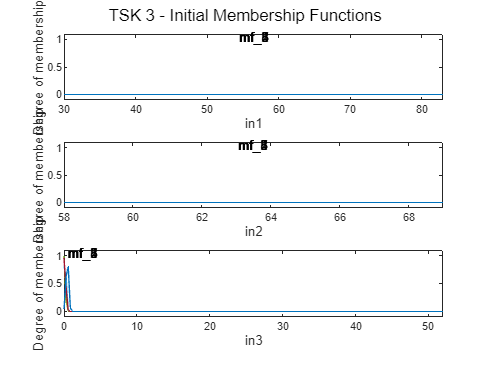

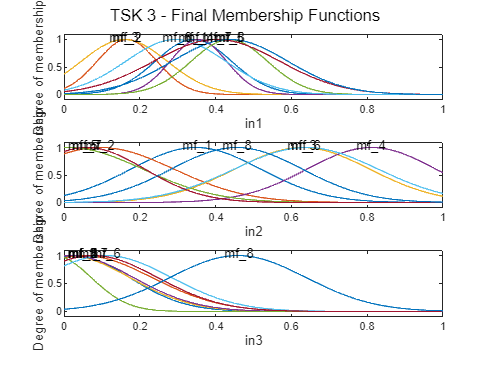

stats_graphs(3, tsk3_valFIS, tsk3_initFIS, chkData, tsk3_trainError, tsk3_valError);

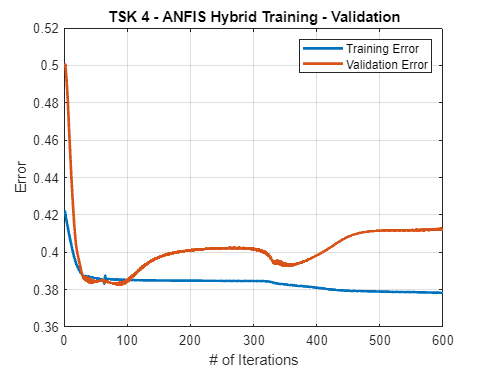

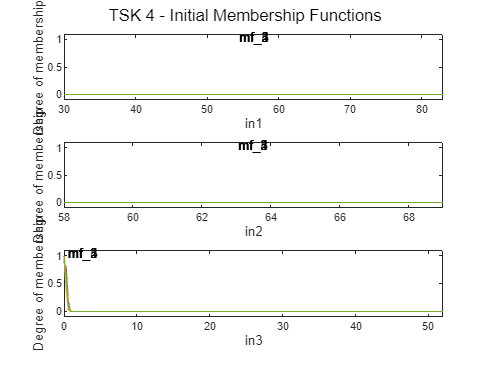

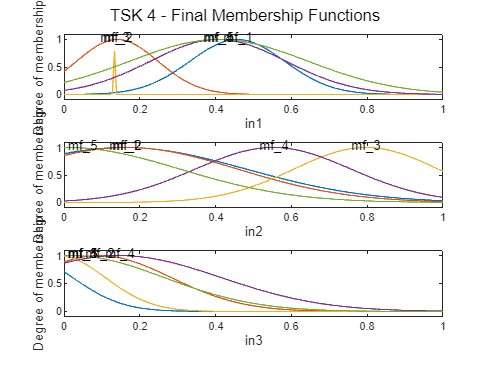

stats_graphs(4, tsk4_valFIS, tsk4_initFIS, chkData, tsk4_trainError, tsk4_valError);